# exercise 3

## P5

syms theta phi r delta L
K = [sin(delta), -cos(delta), -L*cos(delta);
    cos(delta), sin(delta), L*sin(delta);
    0,1,0]

$$K = \left(\begin{array}{ccc} \sin\left(\delta \right) & -\cos\left(\delta \right) & -L\,\cos\left(\delta \right)\\ \cos\left(\delta \right) & \sin\left(\delta \right) & L\,\sin\left(\delta \right)\\ 0 & 1 & 0 \end{array}\right)$$

## P6

R = rotz(theta)

$$R = \left(\begin{array}{ccc} \cos\left(\theta \right) & \sin\left(\theta \right) & 0\\ -\sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

simplify(inv(K))

$$ans = \left(\begin{array}{ccc} \sin\left(\delta \right) & \cos\left(\delta \right) & 0\\ 0 & 0 & 1\\ -\frac{\cos\left(\delta \right)}{L} & \frac{\sin\left(\delta \right)}{L} & -\frac{1}{L} \end{array}\right)$$

k = simplify(inv(R)*inv(K)*[r*phi; 0; 0])

$$k = \left(\begin{array}{c} \varphi \,r\,\sin\left(\delta \right)\,\cos\left(\theta \right)\\ \varphi \,r\,\sin\left(\delta \right)\,\sin\left(\theta \right)\\ -\frac{\varphi \,r\,\cos\left(\delta \right)}{L} \end{array}\right)$$

## P7

## P8

global pose ts robotbar P

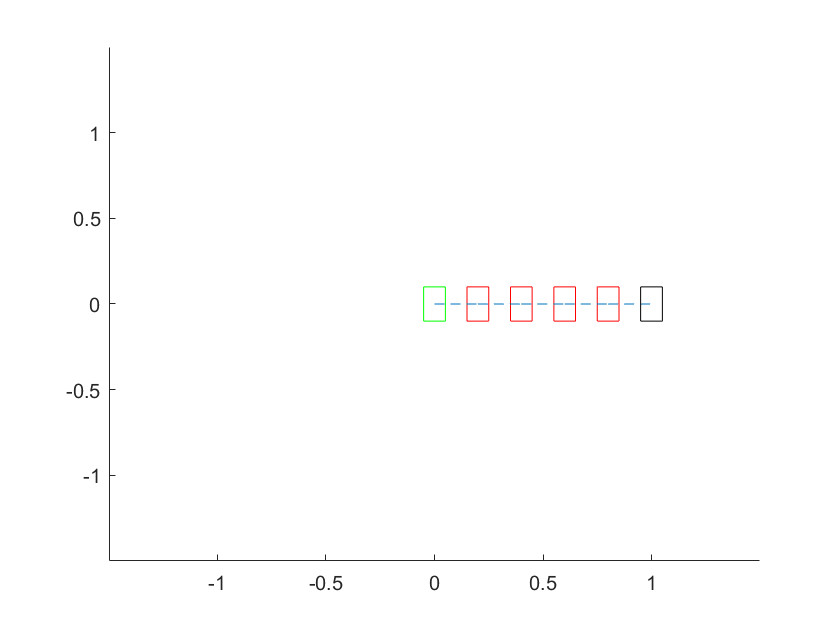

robotbar = [0.26, 0.035, 0.035];
ts = 0.01;
w = [5.714, 5.714];
t = 5;
pose = [0;0;0];
P = []; % store the pose
P = [P,pose];
for i = ts:ts:t
    newpose=kinupdate(pose,robotbar,ts, w);
    pose = newpose;
    P = [P, pose];
end
%plot(P(1,:))
See(100, 1.5); % Let's see the process

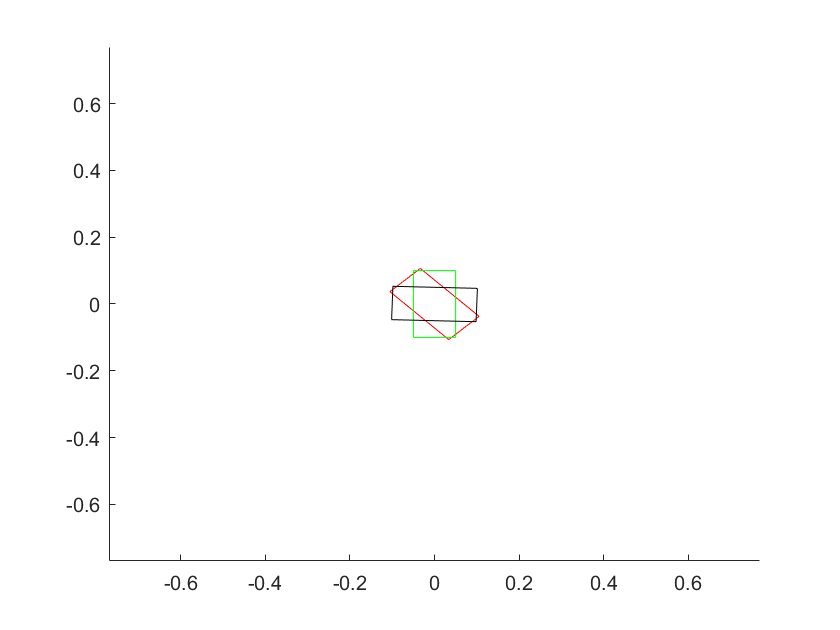

robotbar = [0.26, 0.035, 0.035];
ts = 0.01;
w = [2.86, -2.86];
t = 2;
pose = [0;0;0];
P = []; % store the pose
P = [P,pose];
for i = ts:ts:t
    newpose=kinupdate(pose,robotbar,ts, w);
    pose = newpose;
    P = [P, pose];
end
See(100, 0.5);

## P9

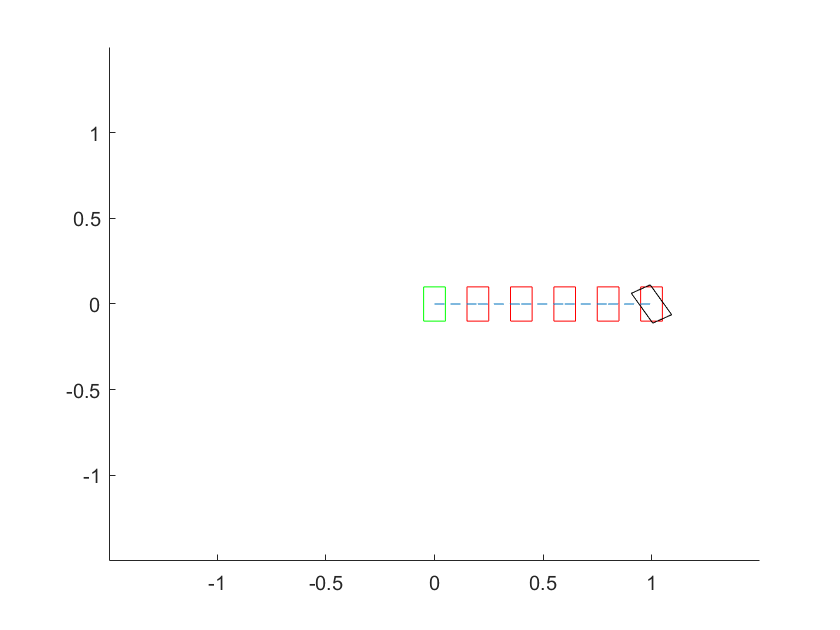

pose = [0;0;0];
P = []; % store the pose
P = [P,pose];
forward(1);
turn(pi/6);
See(100, 1.5);

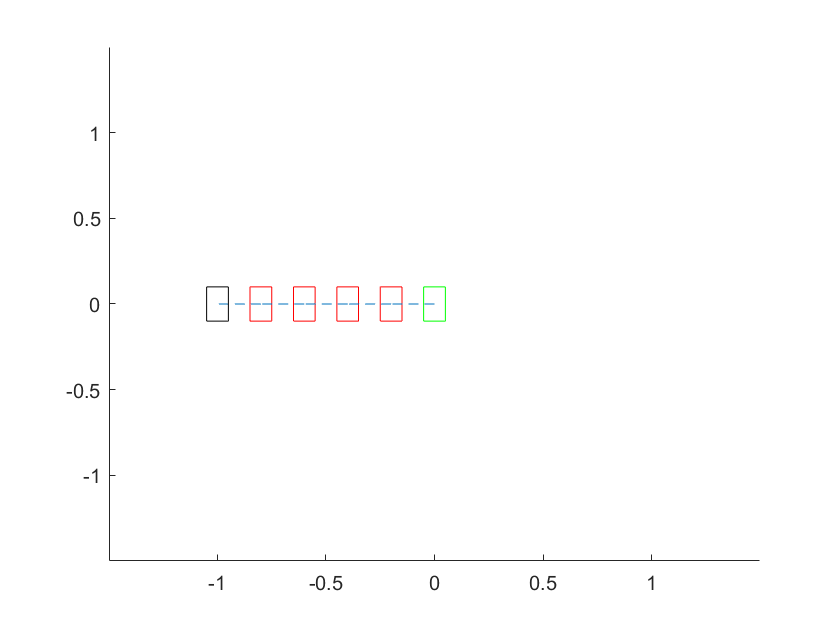

pose = [0;0;0];
P = []; % store the pose
P = [P,pose];
forward(-1)
See(100, 1.5);

## P10

pose = [0;0;0];
P = []; % store the pose
P = [P,pose];
turn(pi/2)
See(100, 0.5);

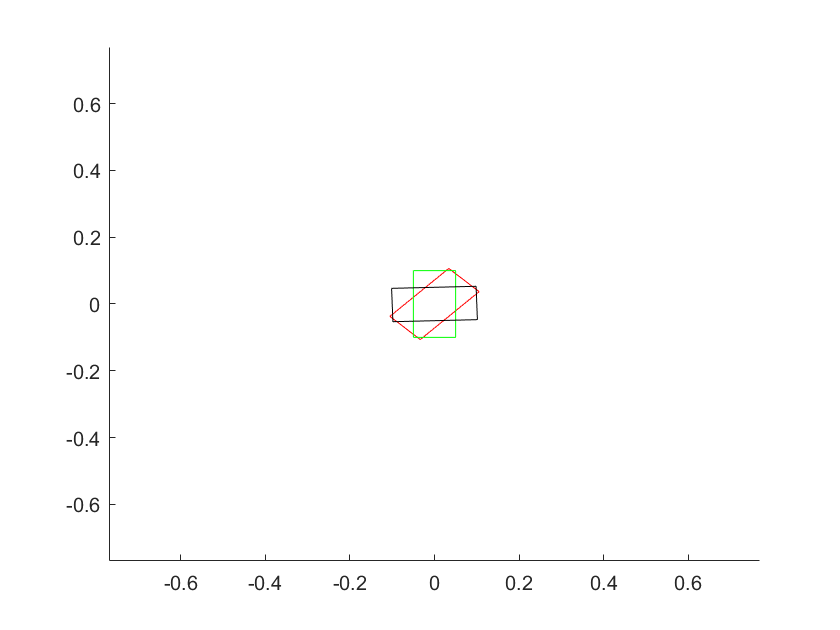

pose = [0;0;0];
P = []; % store the pose
P = [P,pose];
turn(-pi/2)
See(100, 0.5);

## P11

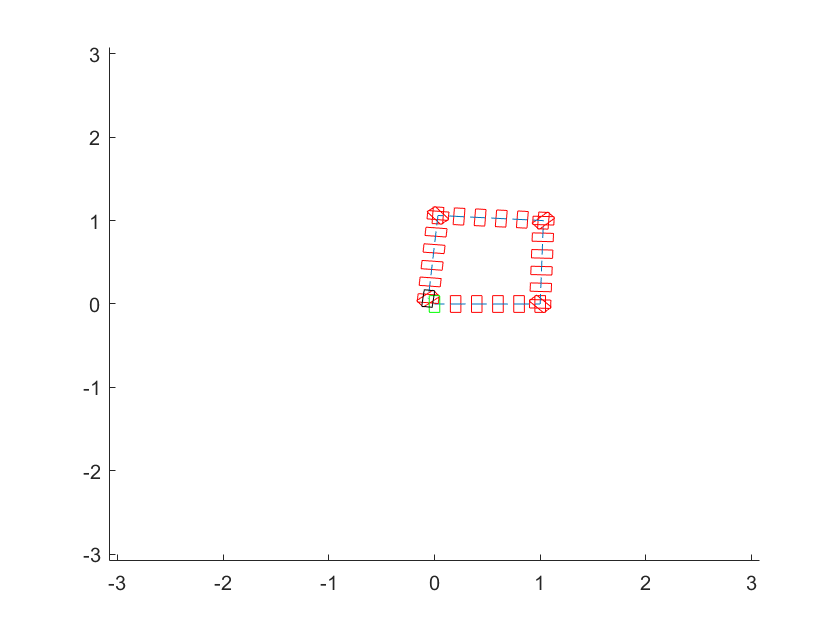

% Square
pose = [0;0;0];
P = []; % store the pose
P = [P,pose];
forward(1);
turn(pi/2);
forward(1);
turn(pi/2);
forward(1);
turn(pi/2);
forward(1);
turn(pi/2);
See(100, 0.5);

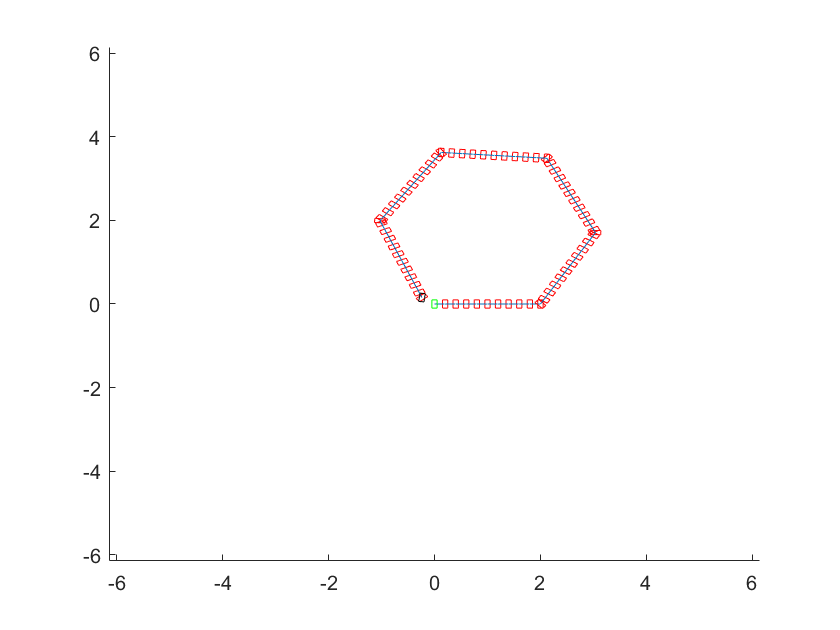

% hexagon
pose = [0;0;0];
P = []; % store the pose
P = [P,pose];
forward(2);
turn(pi/3);
forward(2);
turn(pi/3);
forward(2);
turn(pi/3);
forward(2);
turn(pi/3);
forward(2);
turn(pi/3);
forward(2);
turn(pi/3);
See(100, 1);

## star

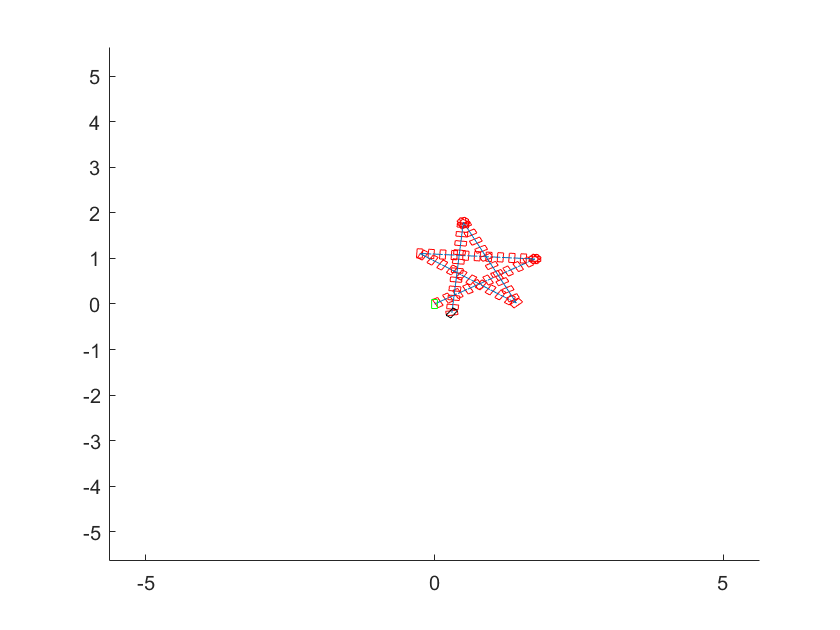

pose = [0;0;0];
P = []; % store the pose
P = [P,pose];
turn(pi/6);
forward(2);
turn(5*pi/6);
forward(2);
turn(-pi/6);
forward(-2);
turn(-pi/6);
forward(2);
turn(5*pi/6);
forward(2);
turn(pi/3);
See(100, 1);

global P;
log = load("odoPose.log");
P = log(:,2:4);
P = P';
P(1,:) = P(1,:)+0.25;
P(2,:) = P(2,:)+0.45;
%P(:,1:2732) = [];

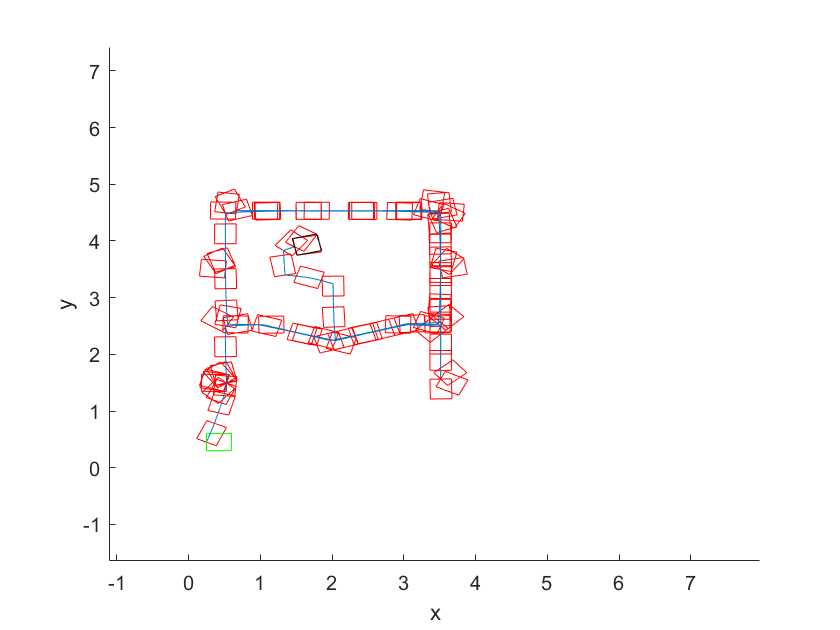

See(150,1);
xlabel("x");
ylabel("y");